# Frequency Input

load('20_02_f.mat');

Input values

y1=scope.signals(1).values; 

y1=y1.';
x1=tout;
x1=x1.';

figure
plot(x1,y1);
hold on


Response values

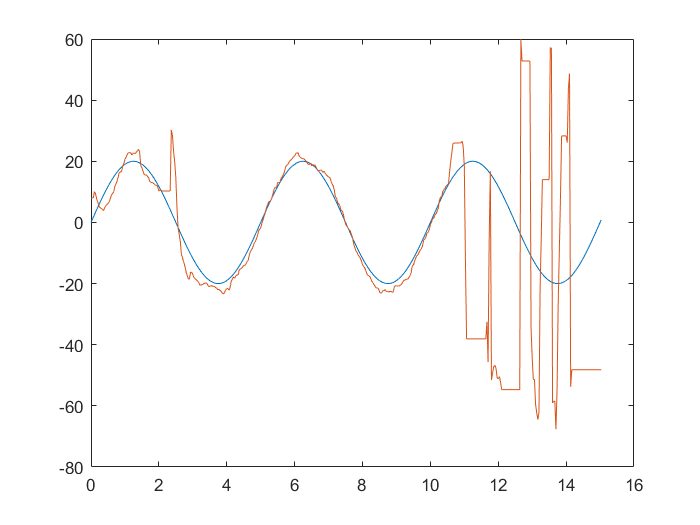

y2=scope.signals(2).values; 

y3=squeeze(y2);
y3=y3.';
constref=80;
y3=y3-constref;

plot(x1,y3);
hold off

Chosing points

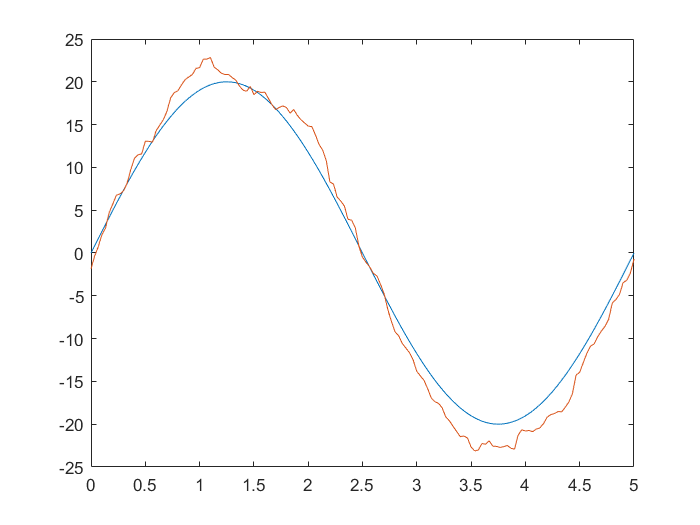

chosen_ref=y1(151:301);
chosen_t=x1(1:151);

plot(chosen_t,chosen_ref);
hold on

chosen_y=y3(151:301);

plot(chosen_t,chosen_y);
hold off

Finding data

Ts=1/30;

[gain, phase, w] = findbodedata2(chosen_ref, chosen_y, Ts, 0)

gain = 0.9961

phase = -0.5710

w =     0.7363    0.7363


Comparing data

figure
semilogx(w,gain,'o','MarkerSize',10)
hold on

bode(Gs_30_final)
hold on

semilogx(w,phase,'o','MarkerSize',10)
hold on

bode(Gs_levy)
hold off